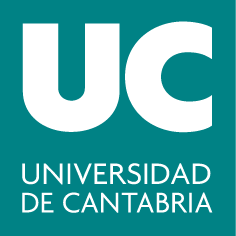

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Introducción a MATLAB**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Familiarizarse con el entorno MATLAB

- Uso de MATLAB como calculadora

- Crear vectores y matrices

**Funciones de MATLAB utilizadas en este guion: **`log, sqrt, exp, cos, sin, linspace, clear all, clc`

## **1. Introducción**

### Interfaz principal de MATLAB

 La interfaz principal de MATLAB se divide en varias partes:

- Las órdenes a ejecutar se escriben en el ***Command Window***** (ventana de comandos)**.

- En el editor (ventana *Editor*) es donde escribimos código que guardaremos en scripts (con extensión *.m) *o live scripts (extensión *.mlx*), para su posterior ejecución desde el *Command Window*.  

- La ventana ***Workspace*** (espacio de trabajo) proporciona información sobre las variables que están almacenadas en memoria durante la sesión activa.

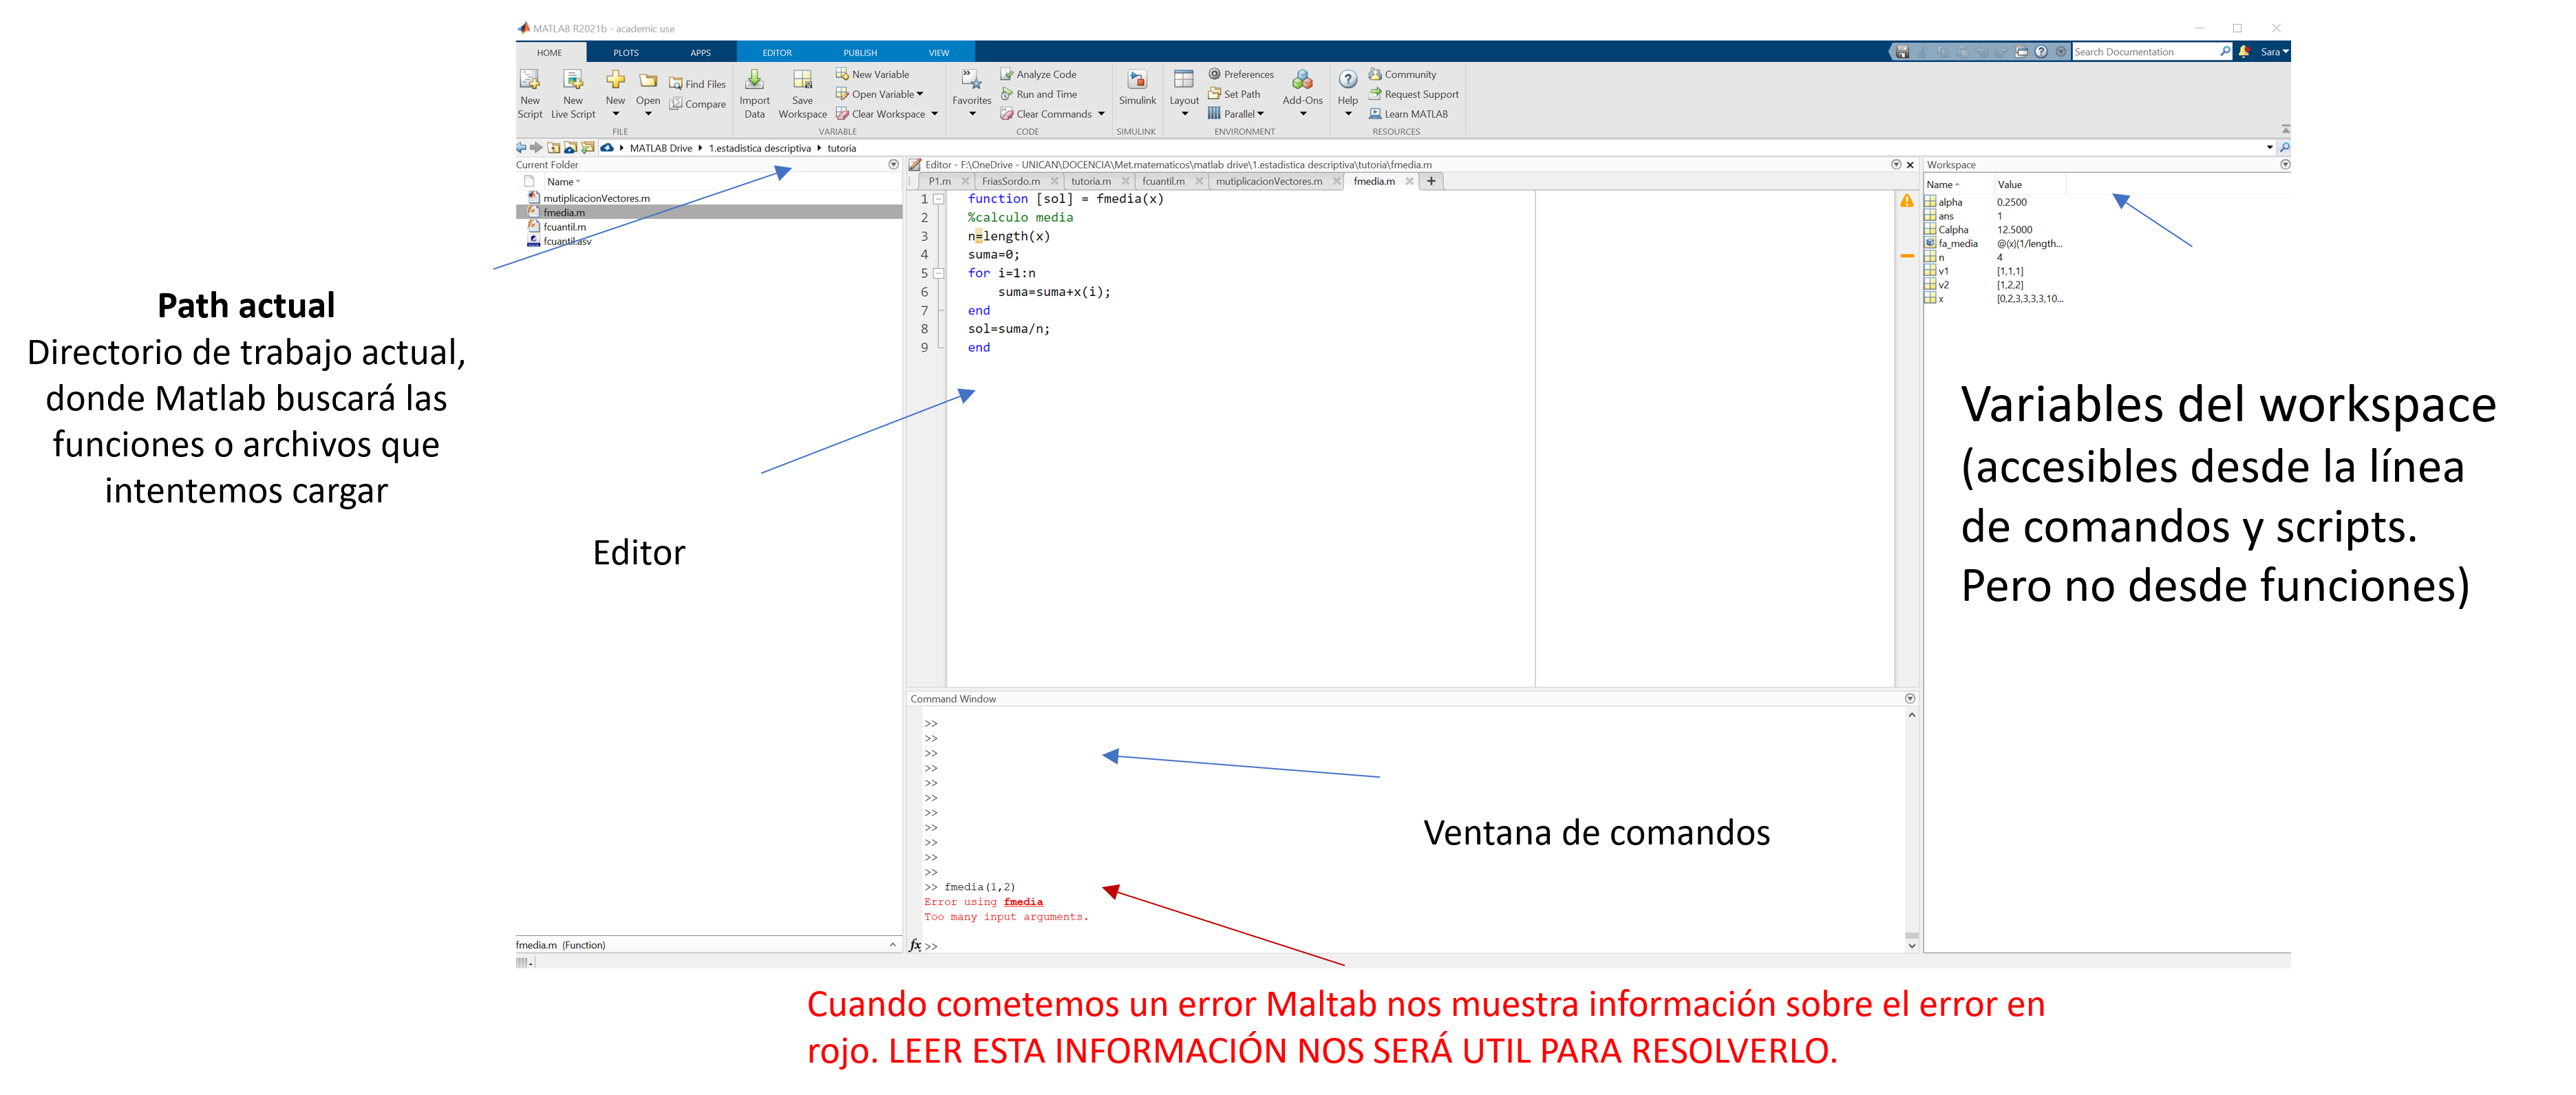

Si al abrir MATLAB no tiene un aspecto similar al de la imagen puede que tengas seleccionado otra configuración de layout. Para poner el layout o disposición de los elementos por defecto selecciona Layout$\to$Default en la pestaña Home.

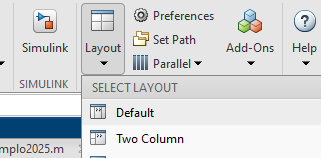

### **Reglas para los nombres de las variables**

Hay ciertas reglas para los nombres de las variables en MATLAB:

- Su nombre puede tener como máximo 63 caracteres que pueden ser letras, números y el guión bajo.

- El primer carácter tiene que ser una letra: *matriz2* es un nombre válido, *2matriz* no lo es.

- Es sensible a mayúsculas y minúsculas: la variable *X* es distinta de la variable *x*.

- No puede haber espacios en blanco: *modulo1 *es un nombre de variable válido, *modulo 1* no.

- Existen nombres que deben evitarse porque tienen significado propio en MATLAB: *ans*, *pi*, *Inf*, *i*, . . .

### Comentarios, texto y visualización de resultados

- Para escribir un comentario de texto que no se ejecute como código se utiliza el símbolo " %". 

%esta es un comentario y no se ejecuta
a=2
%a=3
a

Al programar en MATLAB, usar `%` para añadir comentarios ayuda a que tu código sea fácil de entender, no solo para ti en el futuro, sino también para cualquier otra persona que lo lea.

- Si se escribe el caracter **"*****;"*** al final de una línea de código, dicha línea es ejecutada, pero el resultado de la ejecución no se muestra por pantalla.

a=2;%al finalizar la linea de codigo con ";" el valor de a no se mostrará
b=3

### Variables y memoria en MATLAB: clear all y clc

MATLAB trabaja manteniendo las variables en memoria mientras la sesión está activa. Cada vez que definimos una variable, esta se almacena en el Workspace y permanece disponible hasta que se sobrescribe, se elimina o se cierra MATLAB.

Si se asigna un nuevo valor a una variable ya existente, MATLAB sobrescribe el valor anterior sin mostrar ningún aviso. Por ejemplo:

a=5 % al ejecutar esta instrucción se crea una variable con nombre a que toma el valor 5
a=2 % se sobreescribe la variable a, que pasa a valer 2.+ 

Tras la segunda instrucción, el valor anterior de a se pierde y en memoria solo queda el nuevo valor.

Para evitar confusiones, especialmente al trabajar con scripts o live scripts, es recomendable limpiar la memoria antes de comenzar una sesión de trabajo. Para ello se utilizan las siguientes funciones como:

clear all   % cuando la ejecutamos elimina todas las variables del Workspace
clc         % limpia la ventana de comandos

Ten en cuenta que al ejecutar con "Run" todo el guion de este live script clear all solo afecta a todo el código anterior, pero no se borrarán las variables definidas desde este punto del guion en adelante. Recuerda, **MATLAB siempre ejecuta de arriba a abajo.**

Prueba tú a ejecutar clear all en la Command Window (ventana de comandos)

### Tipos de archivos en MATLAB

MATLAB permite trabajar con distintos tipos de archivos:

- **Scripts** **(.m):** Estos son archivos de texto que contienen secuencias de comandos MATLAB. Pueden incluir comentarios, que se indican con el símbolo `%`, para explicar el código y hacerlo más comprensible.

- **Funciones (.m):** Al igual que los scripts, las funciones también usan la extensión `.m`. Cada archivo de función lleva el nombre de la función que define. Las funciones son muy útiles para implementar un determinado procedimiento que vamos a utilizar en distintas ocasiones. MATLAB tiene implementadas muchas funciones, como por ejemplo la función det() que calcula el determinante de una matriz. Aprenderemos a implementar nuestras propias funciones en las siguientes sesiones de prácticas.

- **Live Scripts (.mlx): **Estos archivos interactivos permiten combinar código, texto formateado, ecuaciones y medios visuales como imágenes y gráficos. Un Live Script se puede exportar a formatos como HTML o PDF para facilitar su visualización. El documento que estás leyendo se ha generado usando este tipo de archivo. 

Para nombrar los archivos de MATLAB utilizar un nombre sin espacios y que comience por una letra (no un número). Podemos utilizar el guion bajo '_' en el nombre de los archivos.

#### Formatos de visualización de los resultados numéricos

MATLAB ofrece distintos formatos para la visualización de los resultados numéricos. 

Es importante entender que estos comandos afectan únicamente la visualización: MATLAB continúa realizando cálculos con la precisión completa de los datos en punto flotante, que típicamente es de doble precisión y utiliza 64 bits.

- `format short`**: **Muestra 4 cifras decimales, y es el formato por defecto

format short  % o simplemente "format": 4 cifras decimales
1/3

- `format long`: Aumenta la visualización a 15 cifras decimales.

format long  % 15 cifras decimales
1/3

- **format ra**`t:` Presenta los números como fracciones o números racionales.

format rat  % formato racional
1/3

format  % volvemos al formato corto de 4 cifras decimales (formato usado por defecto)

### Documentación y ayuda

Los comandos `help, doc y lookfor` sirven para obtener ayuda sobre el resto de comandos/funciones. La documentación online de MATLAB (accesible mediante *doc*) es realmente buena.

El comando `help` nos permite obtener una ayuda resumida del uso de una función o comando de MATLAB.

help diag

El comando `lookfor` nos permite buscar funciones de MATLAB que contengan una palabra como 'diagonal' en el nombre o en su definición.  

lookfor diagonal

## 2. Operaciones básicas: MATLAB** como calculadora**

La forma de operar con MATLAB es igual que con una calculadora de bolsillo, usando los símbolos *+, -, *, /, ^*. Por ejemplo:

- Suma y resta:

2+4
2-4

- Multiplicación y división:

2*pi
pi/10

- Potenciación:

3^2

- Otros operadores importantes:

sqrt(4)  % raíz cuadrada
log(1)  % logaritmo neperiano
exp(1)  % exponencial
sin(pi/2)  % seno
cos(pi/2)  % coseno  (debería dar 0, MATLAB nos da una aproximacion)

## **3. Matrices**

### Definición de vectores y matrices

#### Definición** de vectores **

Para definir un vector fila usamos corchetes y separamos sus elementos por espacios o comas:

a = [1 4 9]
a = [1, 4, 9]  % podemos dejar un espacio en blanco entre números o poner una coma

Para crear un **vector columna** separamos sus elementos por ";". 

b=[1; 4; 4]

Otra opción es crear un vector fila y trasponerlo utilizando la comilla

b = [-1  2  3  5 9  11 -2]'

**Definición de vectores con elementos equiespaciados.** En este caso resultan muy prácticas estas dos opciones:

- mediante el uso de ":" definimos un vector como indicando el elemento inicial, el paso y el elemento final

a = 1:2:10  % secuencia entre 1 y 10, que van de 2 en 2

- mediante el uso de la función `linspace` 

`linspace(x1,x2,N)`

donde x1 es el elemento inicial, x2 el elemento final y N el número de elementos del vector

linspace(1,9,5) 

#### Definición de matrices

Para definir una matriz combinamos la definición de vector fila y vector columna. Cuando escribimos ";" es un salto de fila.  Por ejemplo:

M = [1 2 3; 4 5 6]  % matriz de 2 filas y 3 columnas
A = [1 2 1; 2 4 3; 3 5 2]  % matriz de 3 filas y 3 columnas

### **Acceso a los elementos de una matriz **

Se pueden seleccionar elementos de una matriz indicando, entre paréntesis, la posición de la fila y la columna.

A(1, 3)  % elemento de la primera fila y tercera columna

Para extraer filas o columnas enteras se utiliza el símbolo "`:`*".* Cuando escribimos  "`:`*" en las columnas estamos indicando que queremos todas las columnas.*

Por ejemplo, si queremos acceder a la segunda fila indicaremos con "`:`" que queremos acceder a todas las columnas. Obteniendo para A los elementos [$a_{2,1} ,$$a_{2,2} ,$$a_{2,3}$]

A(2, :)  % fila 2  
A(:, 1)  % columna 1
A(:, 1:2) % columnas 1, 2 
A(:, [1, 3]) % columnas 1 y 3
b(3:5)  %elementos 3 al 5 del vector columna

Para extraer la diagonal principal de una matriz usamos la función diag(). Ya vimos anteriormente que la función diag también sirve para definir una matriz diagonal. Esta función tiene distintos usos dependiendo de qué argumentos pasemos, si le pasamos una matriz nos devolverá su diagonal principipal, y si le pasamos un vector nos construirá una matriz diagonal. 

d = diag(A) %acceso a los elementos de la diagonal de A

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.